[X, Y, Z]=spectra2xyz(R1, CIED65); %test

%1.1
[X, Y, Z]=spectra2xyz(1, CIED65)    

X = 95.0437

Y = 100

Z = 108.8818

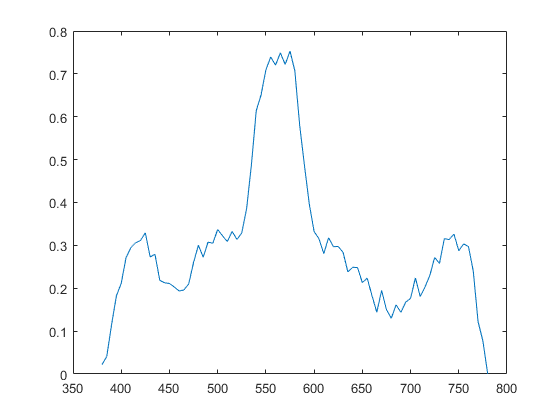

%1.2
plot(wavelength, R1)

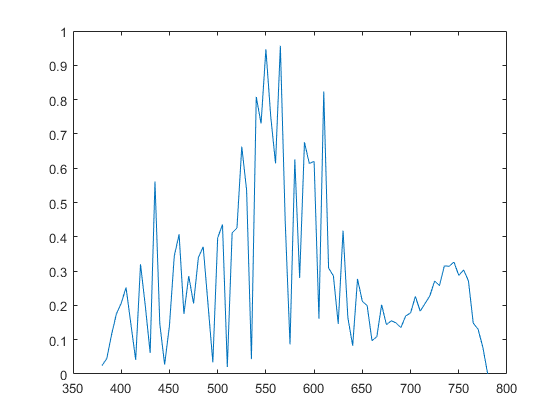


plot(wavelength, R2)


[X1, Y1, Z1]=spectra2xyz(R1, CIED65)    

X1 = 40.0489

Y1 = 49.7395

Z1 = 26.6104

[X2, Y2, Z2]=spectra2xyz(R2, CIED65)   

X2 = 40.0489

Y2 = 49.7395

Z2 = 26.6104

%1.3
[X3, Y3, Z3]=spectra2xyz(R1, f11)    

X3 = 41.6587

Y3 = 53.3569

Z3 = 16.3345

[X4, Y4, Z4]=spectra2xyz(R2, f11)

X4 = 53.9818

Y4 = 63.4675

Z4 = 20.7173

%plot(wavelength, [X, Y, Z])

%1.4
%metamerism

%1.5
[r1,g1,b1] = myxyz2rgb(X1,Y1,Z1)

r1 = 0.4005

g1 = 0.5560

b1 = 0.2022

[r2,g2,b2] = myxyz2rgb(X2,Y2,Z2)

r2 = 0.4005

g2 = 0.5560

b2 = 0.2022

[r3,g3,b3] = myxyz2rgb(X3,Y3,Z3)

r3 = 0.4483

g3 = 0.6040

b3 = 0.0870

[r4,g4,b4] = myxyz2rgb(X4,Y4,Z4)

r4 = 0.6704

g4 = 0.6760

b4 = 0.1196

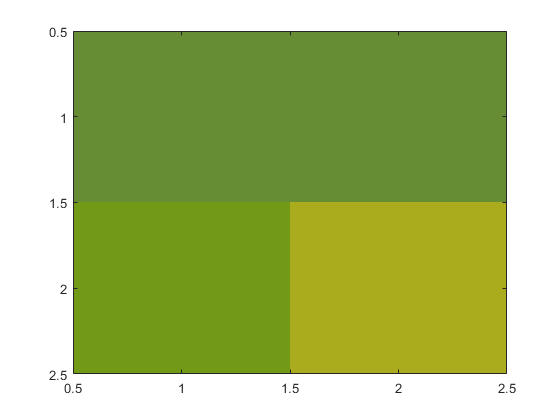


map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4];
map=min(1,max(0,map));
image([1 2; 3 4])
colormap(map)

%2.1

b = 0.5;
p = 0.5;

%dot on dot
xtot1 = 0.5*(80.43 + 7.4);
ytot1 = 0.5*(84.00 + 5.74);
ztot1 = 0.5*(96.50 + 40.36);

c = 0.5;
m = 0.5;
%dot off dot
xtot2 = 0.5*(25.84 + 37.36)

xtot2 = 31.6000

ytot2 = 0.5*(42.52 + 18.44)

ytot2 = 30.4800

ztot2 = 0.5*(80.88 + 27.52)

ztot2 = 54.2000

%2.2
[r1,g1,b1] = myxyz2rgb(80.43,84.00,96.50)

r1 = 0.8340

g1 = 0.8364

b1 = 0.8937

[r2,g2,b2] = myxyz2rgb(25.84,42.52,80.88)

r2 = 0

g2 = 0.5808

b2 = 0.7828

[r3,g3,b3] = myxyz2rgb(37.36,18.44,27.52)

r3 = 0.7900

g3 = 0

b3 = 0.2741

[r4,g4,b4] = myxyz2rgb(7.40,5.74,40.36)

r4 = 0

g4 = 0.0527

b4 = 0.4191

[r5,g5,b5] = myxyz2rgb(xtot1,ytot1,ztot1)

r5 = 0.3922

g5 = 0.4445

b5 = 0.6564

[r6,g6,b6] = myxyz2rgb(xtot2,ytot2,ztot2)

r6 = 0.2853

g6 = 0.2880

b6 = 0.5285

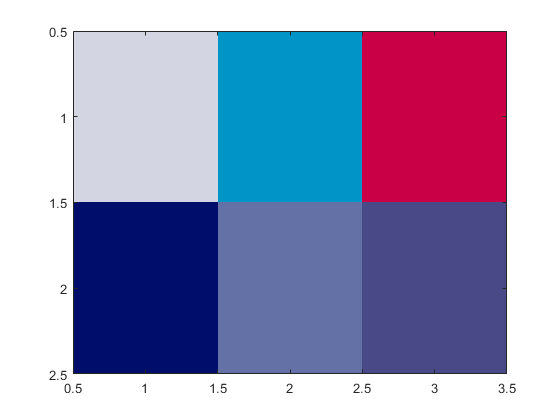


map=[r1 g1 b1; r2 g2 b2; r3 g3 b3; r4 g4 b4; r5 g5 b5; r6 g6 b6];
map=min(1,max(0,map));
image([1 2 3; 4 5 6])
colormap(map)

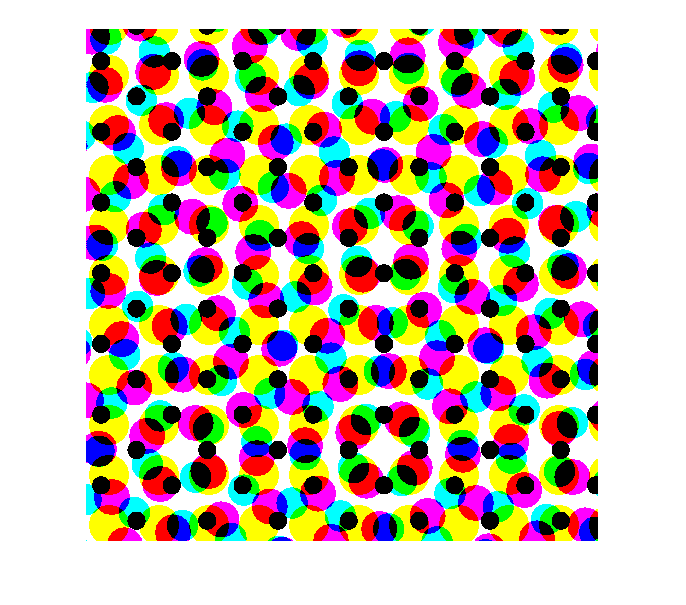

%3.1
[C, M, Y, K]=tiffread('halftone');
[R, G, B]=cmyk2rgb(C, M, Y, K);
imshowrgb(R, G, B)

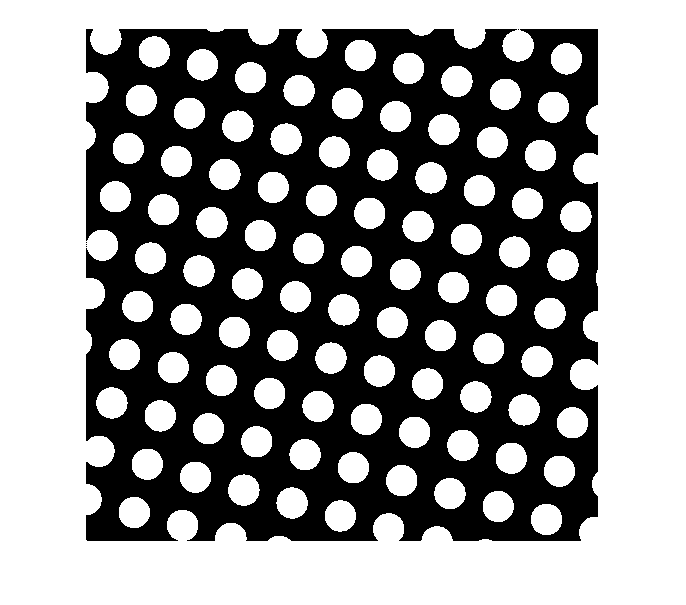

imshow(C)

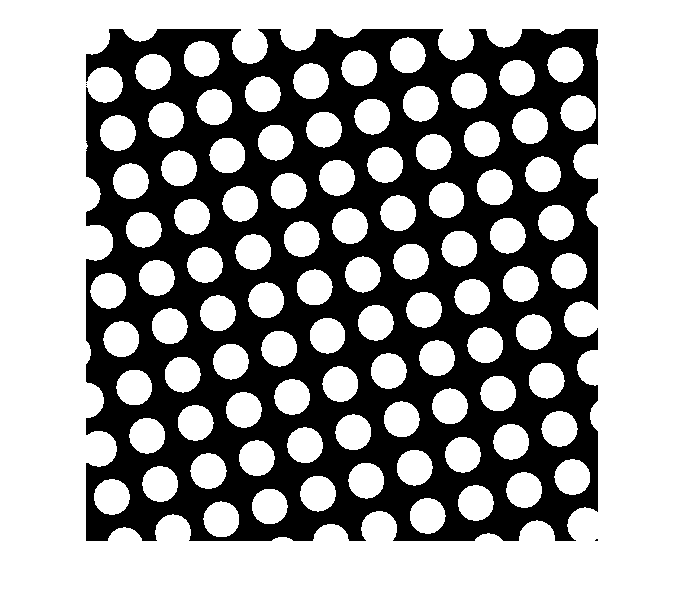

imshow(M)

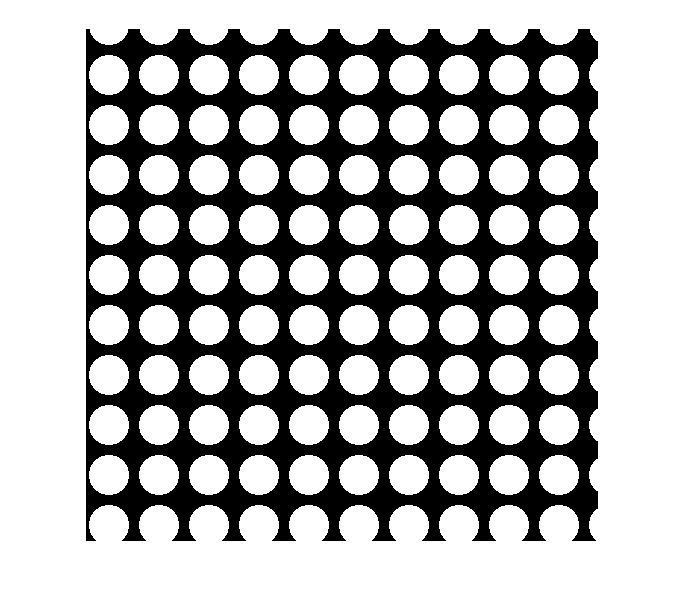

imshow(Y)

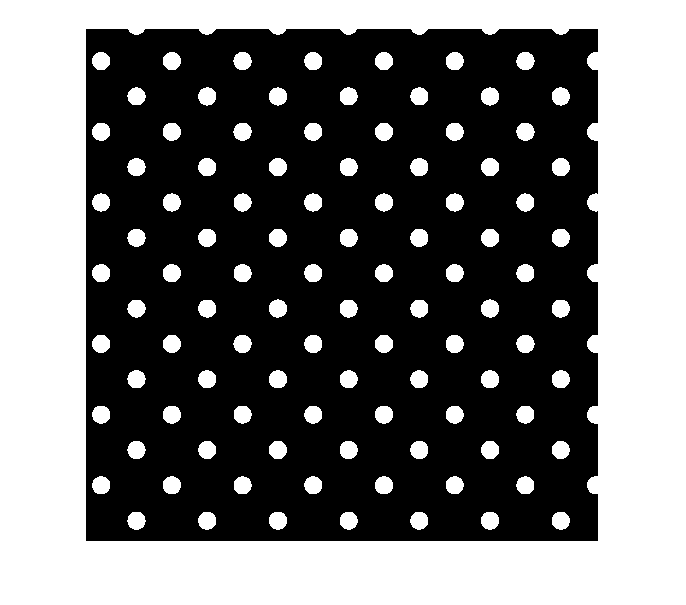

imshow(K)

sum(sum(C & M & ~Y & ~K))/512^2'

ans = 0.0618





C1 = C(129:384,129:384); 
M1 = M(129:384,129:384);
Y1 = Y(129:384,129:384);
K1 = K(129:384,129:384);
out1=Demichel_test(C1,M1,Y1,K1)  

out1 =     0.1628
    0.0765
    0.1351
    0.2090
    0.0191
    0.0648
    0.0858
    0.0096
    0.1126
    0.0185



C2=C(139:394,129:384);
M2=M(139:394,129:384);
Y2=Y(139:394,129:384);
K2=K(139:394,129:384); 

out2=Demichel_test(C2,M2,Y2,K2) 

out2 =     0.1662
    0.0753
    0.1327
    0.2031
    0.0183
    0.0584
    0.0895
    0.0101
    0.1172
    0.0198


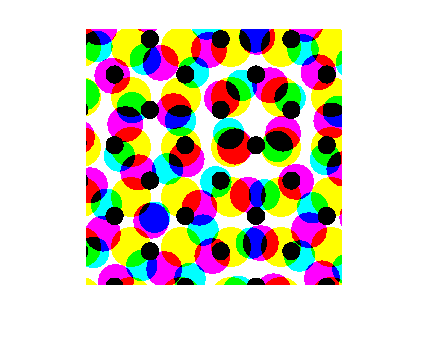


[R, G, B]=cmyk2rgb(C1, M1, Y1, K1);
imshowrgb(R, G, B)

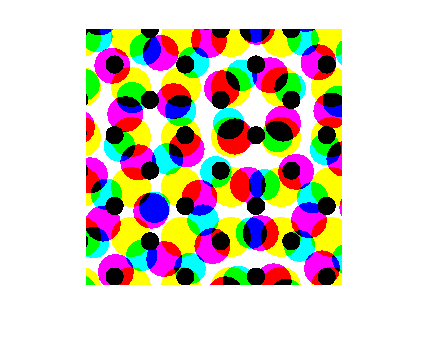

[R, G, B]=cmyk2rgb(C2, M2, Y2, K2);
imshowrgb(R, G, B)

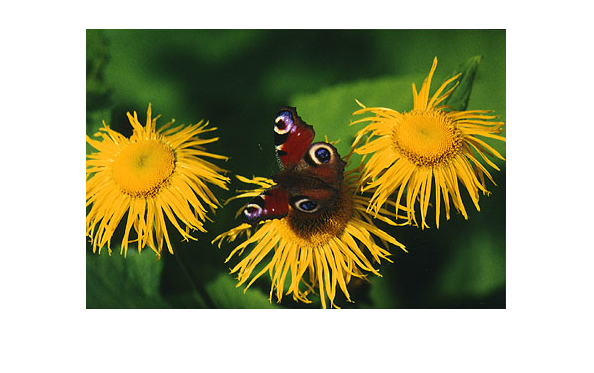

%4.1

[R, G, B]=tiffread('Butterfly');
imshowrgb(R ,G, B)

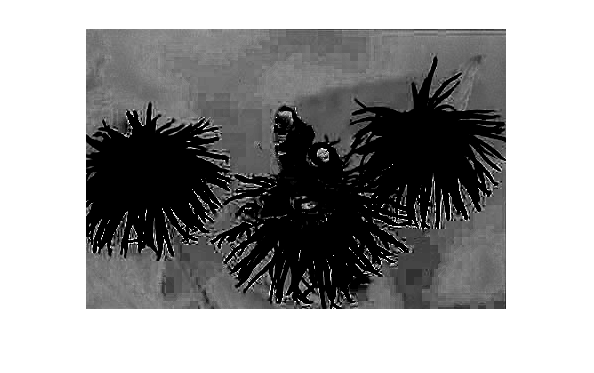

[C, M, Y, K]=rgb2cmyk(R,G,B);
figure(1);
imshow(C)

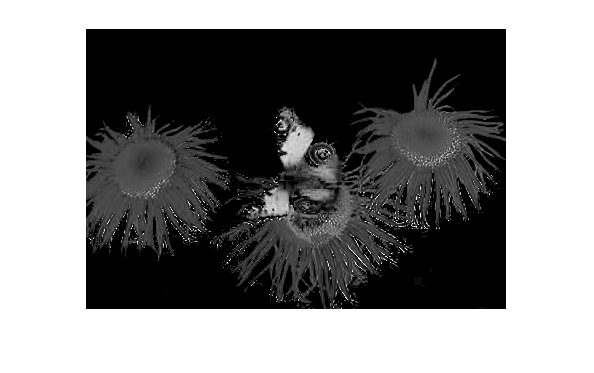

figure(2)
imshow(M)

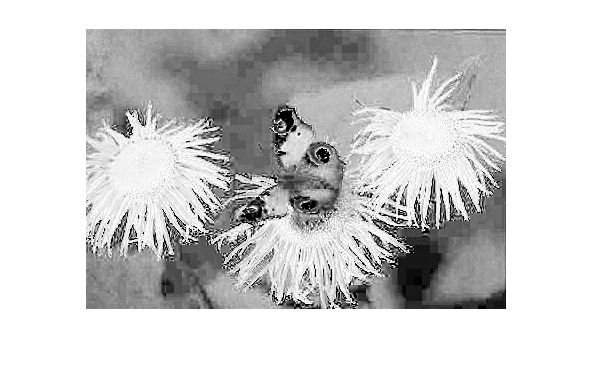

figure(3)
imshow(Y)

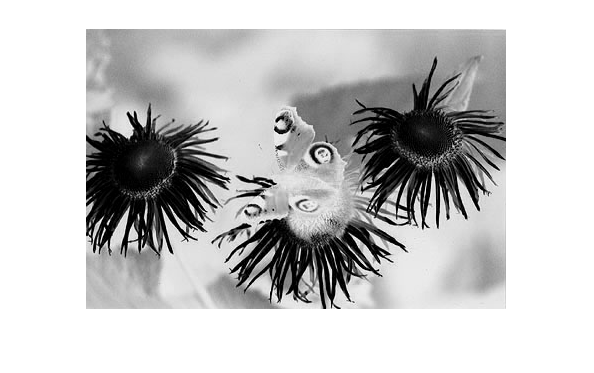

figure(4)
imshow(K)

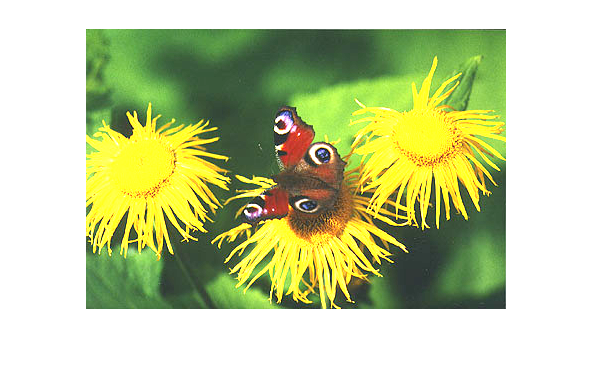

%4.2
[L, a, b]=myrgb2lab(R,G,B);

 [R2, G2, B2]=mylab2rgb(L+20, a, b);
 imshowrgb(R2, G2, B2)

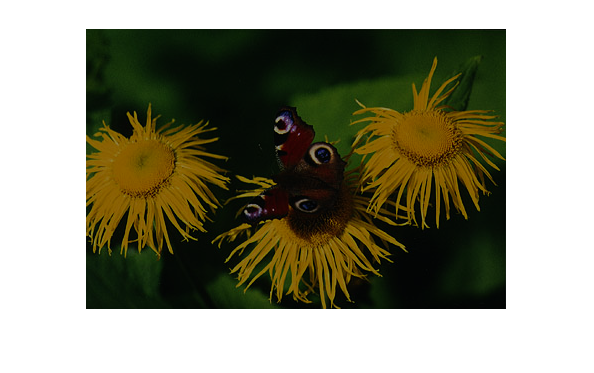

 figure
 [R3, G3, B3]=mylab2rgb(L-20, a, b);
 imshowrgb(R3, G3, B3)

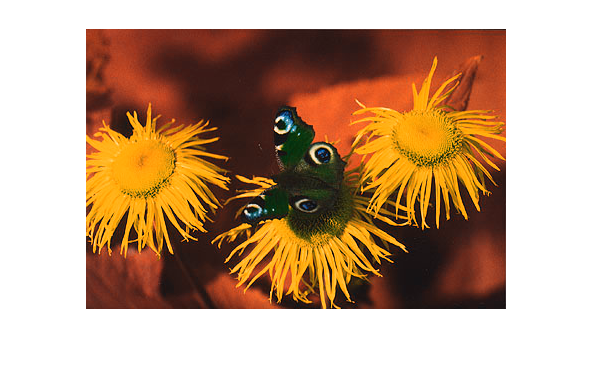

%4.3
[L, a, b]=myrgb2lab(R,G,B);

 [R2, G2, B2]=mylab2rgb(L, -a, b);
 imshowrgb(R2, G2, B2)

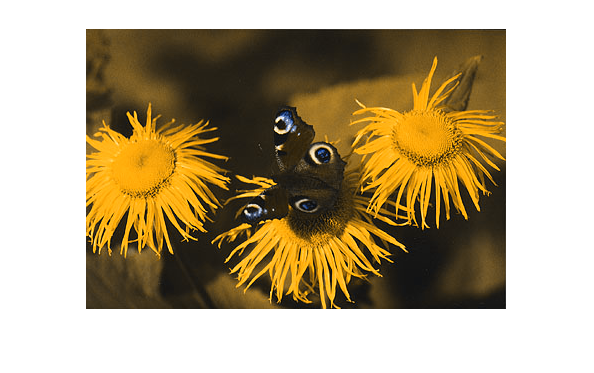

 figure
 [R2, G2, B2]=mylab2rgb(L, 0, b);
  imshowrgb(R2, G2, B2)

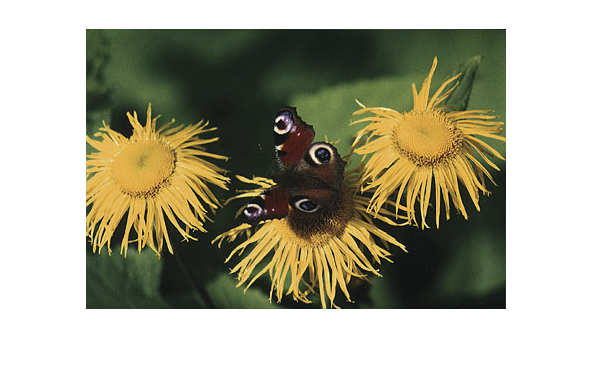

%4.4
[L, a, b]=myrgb2lab(R,G,B);

 [R2, G2, B2]=mylab2rgb(L, 0.5*a, 0.5*b);
 imshowrgb(R2, G2, B2)

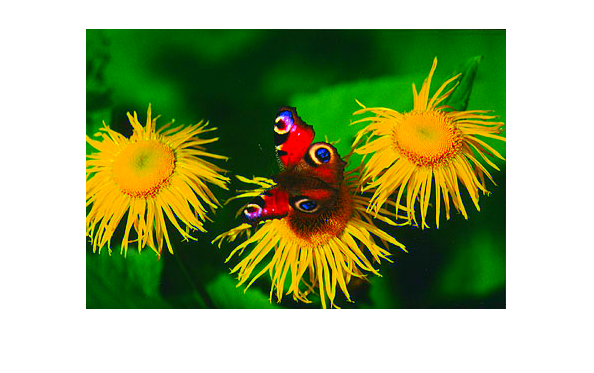

 figure
 [R2, G2, B2]=mylab2rgb(L, 3*a, 3*b);
 imshowrgb(R2, G2, B2)

%5.1
[X1, Y1, Z1]=spectra2xyz(1, CIED65); 
[r1,g1,b1] = myxyz2rgb(X1,Y1,Z1);
%showRGB(r1, g1, b1)

[X2, Y2, Z2]=spectra2xyz(1, Tungsten60W)

X2 = 112.9853

Y2 = 100

Z2 = 28.5810

[r2,g2,b2] = myxyz2rgb(X2,Y2,Z2);
%imshowrgb(R2, G2, B2)

[X3, Y3, Z3]=spectra2xyz(1, plank90K)

X3 = 97.0578

Y3 = 100

Z3 = 141.1759

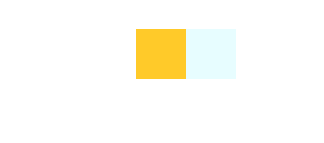

[r3,g3,b3] = myxyz2rgb(X3,Y3,Z3);
%imshowrgb(R2, G2, B2)
RBG_1 = [r1 g1 b1; r2 g2 b2; r3 g3 b3];
showRGB(RBG_1)

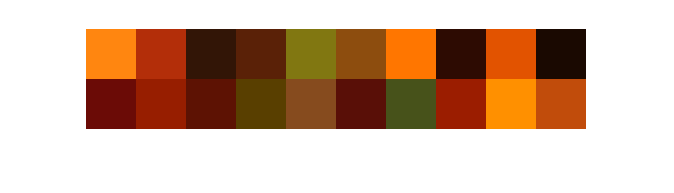

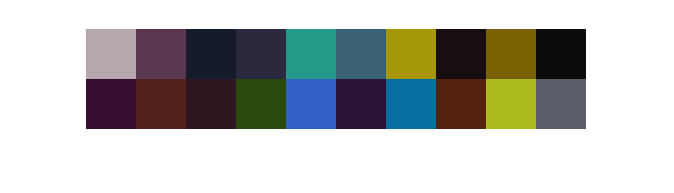

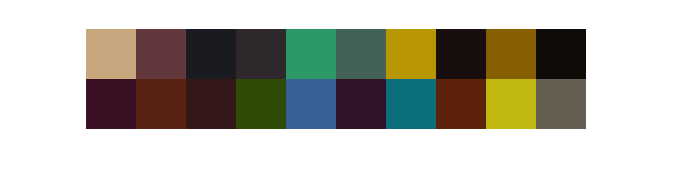

%5.2
showRGB_20

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


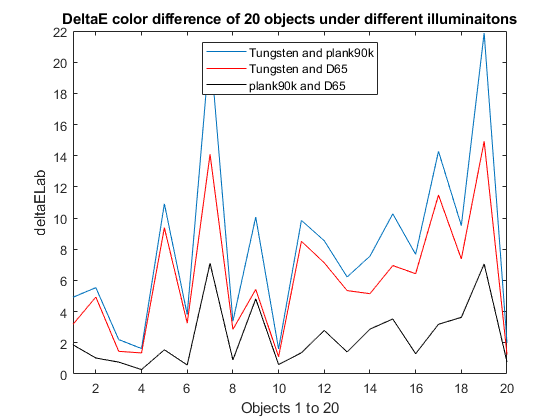

%5.3
plot_deltaE

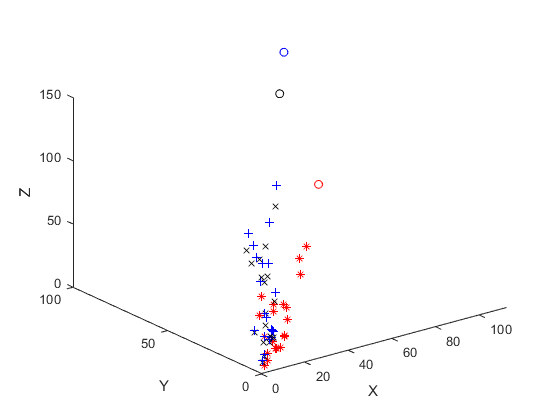

%5.4
plot_XYZ

%5.5
%yes

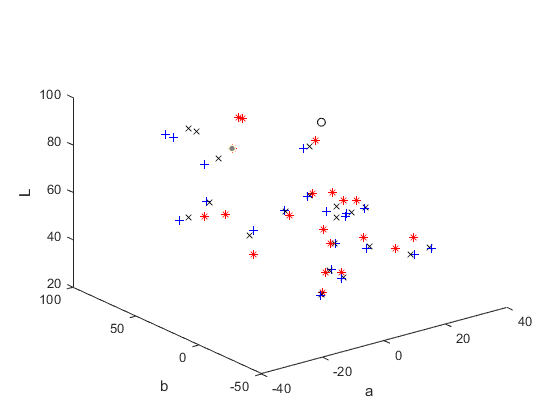

%5.6
plot_Lab